model = alexnet;

dataFolder = './Images';
categories = {'mel','no_mel'};
imds = imageDatastore(fullfile(dataFolder,categories),'LabelSource','foldernames');
tbl = countEachLabel(imds);
disp(tbl)

    Label     Count
    ______    _____

    mel        900 
    no_mel    2041 




minSetCount = min(tbl{:,2});
imds = splitEachLabel(imds,minSetCount,'randomize');
countEachLabel(imds)

ans = 2×2 table
    Label     Count
    ______    _____

    mel        900 
    no_mel     900 


imds.ReadFcn =@(filename)readAndPreprocessImage(filename);


[trainingSet,validationSet,unseenData] = splitEachLabel(imds,0.7,0.2,0.1,'randomized');

countEachLabel(trainingSet)

ans = 2×2 table
    Label     Count
    ______    _____

    mel        630 
    no_mel     630 


countEachLabel(validationSet)

ans = 2×2 table
    Label     Count
    ______    _____

    mel        180 
    no_mel     180 


countEachLabel(unseenData)

ans = 2×2 table
    Label     Count
    ______    _____

    mel        90  
    no_mel     90  



writeall(unseenData,"unseen_images");

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange,...
    'RandYScale',scaleRange);

inputSize = model.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet,'DataAugmentation',imageAugmenter);

disp(augimdsTrain.NumObservations)

        1260




augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet);
disp(augimdsValidation.NumObservations)

   360



layersTransfer = model.Layers(1:end-3);
numClasses = 2;

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer
];

miniBatchSize = 250;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

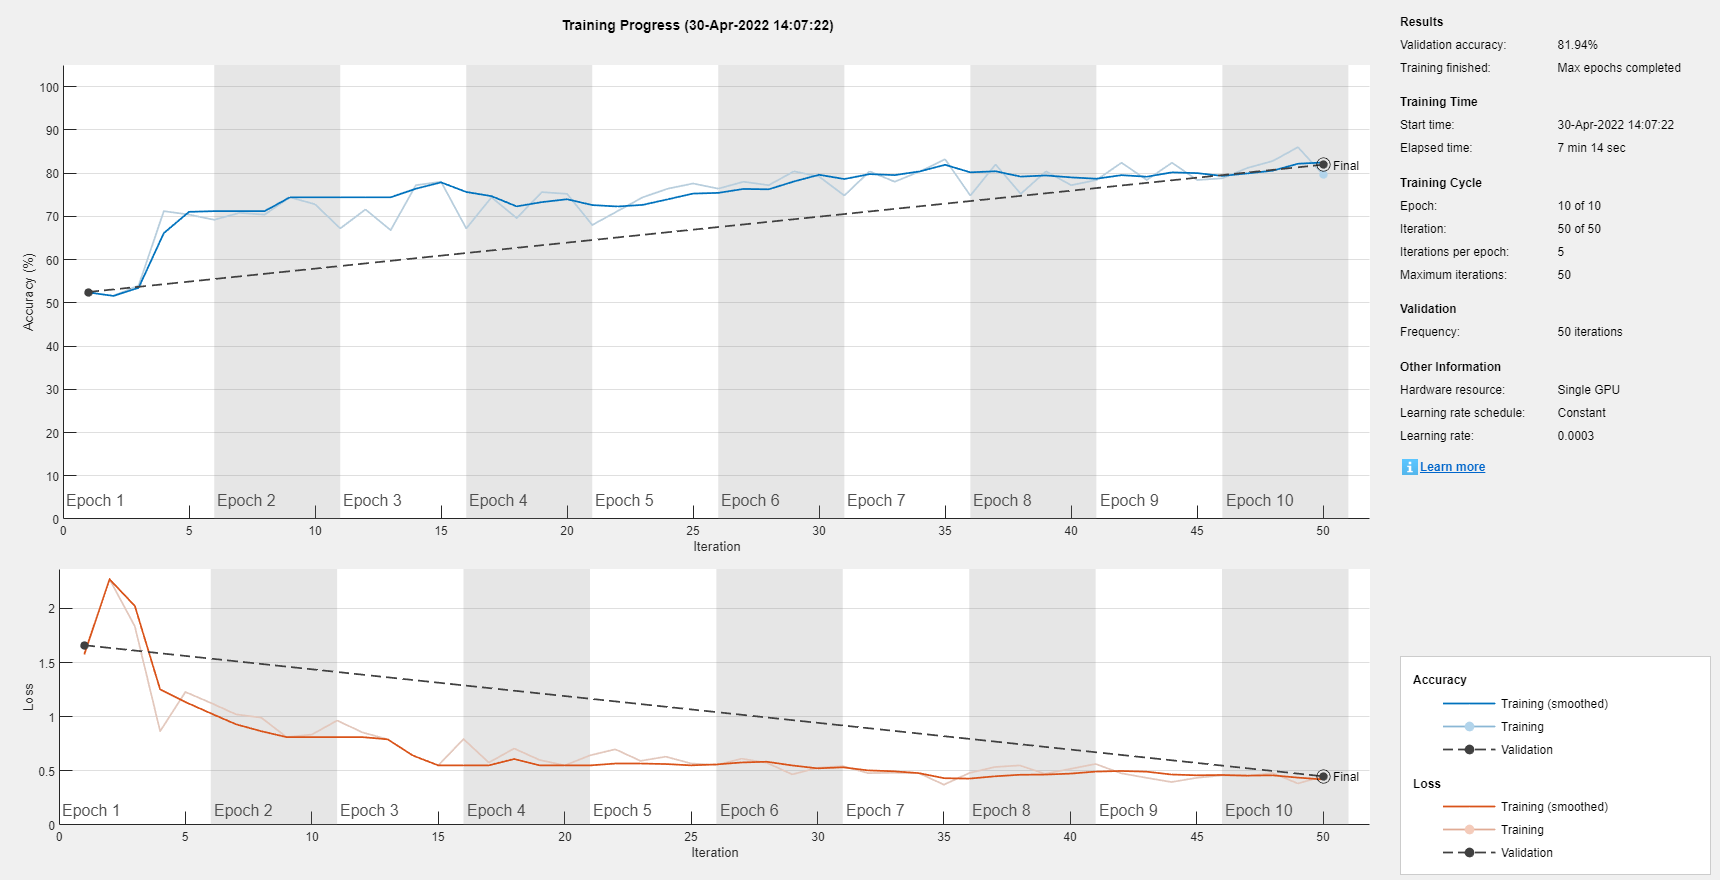

modelAug = trainNetwork(augimdsTrain,layers,options);

[YpredAug,probsAug] = classify(modelAug,augimdsValidation);

YValidationAug = validationSet.Labels;
accuracyAug = mean(YpredAug == YValidationAug);
fprintf("The validation accuracy is: %.2f %%\n",accuracyAug*100);

The validation accuracy is: 81.94 %



Classify_model_aug= modelAug;
save Classify_model_aug;